Complex Fourier Series


$$f(x)=\sum_{n=-k}^{k}C_ne^{in\omega x}$$



$$C_n=\frac{1}{T}\int_{d}^{d+T}f(x)e^{-in\omega x}dx$$


Given $f\left(x\right)=x$ in $\left(-\pi \;,\pi \;\right)$

syms x
T = 2*pi;
w = 2*pi/T;
f = x;
k = 10;
n = -k:k;
Cn = int(f.*exp(-1i*n*w*x), x, -pi, pi)/T;
CFS = sum(Cn.*exp(1i*n*w*x));
CFS = simplify(CFS);
disp(CFS)

$$-\frac{{\mathrm{e}}^{-10\,x\,\mathrm{i}}\,{\left({\mathrm{e}}^{x\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}\right)}^{3}\,\left(476\,{\mathrm{e}}^{x\,\mathrm{i}}+987\,{\mathrm{e}}^{2\,x\,\mathrm{i}}+1425\,{\mathrm{e}}^{3\,x\,\mathrm{i}}+2210\,{\mathrm{e}}^{4\,x\,\mathrm{i}}+2838\,{\mathrm{e}}^{5\,x\,\mathrm{i}}+3939\,{\mathrm{e}}^{6\,x\,\mathrm{i}}+4673\,{\mathrm{e}}^{7\,x\,\mathrm{i}}+6300\,{\mathrm{e}}^{8\,x\,\mathrm{i}}+6300\,{\mathrm{e}}^{9\,x\,\mathrm{i}}+4673\,{\mathrm{e}}^{10\,x\,\mathrm{i}}+3939\,{\mathrm{e}}^{11\,x\,\mathrm{i}}+2838\,{\mathrm{e}}^{12\,x\,\mathrm{i}}+2210\,{\mathrm{e}}^{13\,x\,\mathrm{i}}+1425\,{\mathrm{e}}^{14\,x\,\mathrm{i}}+987\,{\mathrm{e}}^{15\,x\,\mathrm{i}}+476\,{\mathrm{e}}^{16\,x\,\mathrm{i}}+252\,{\mathrm{e}}^{17\,x\,\mathrm{i}}+252\right)}{2520}$$

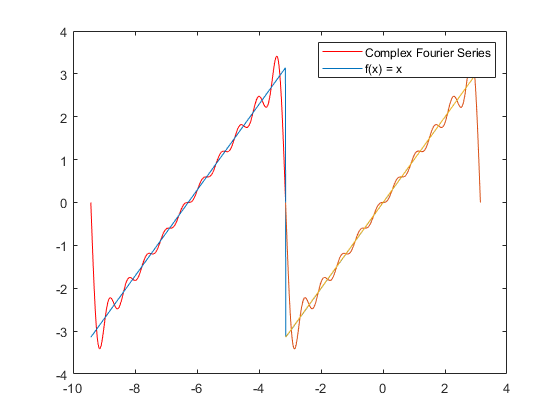

fplot(real(CFS), [-pi pi])
%x = linspace(-pi, pi, 500);
%y = eval(CFS);
%plot(x, y);
hold on;
fplot(f, [-pi pi])
legend('Complex Fourier Series', 'f(x) = x')
hold off

%fplot(real(CFS), [-3*pi pi])
x = linspace(-3*pi, pi, 500);
y = eval(CFS);


$$-\frac{{\mathrm{e}}^{-10\,x\,\mathrm{i}}\,{\left({\mathrm{e}}^{x\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}\right)}^{3}\,\left(476\,{\mathrm{e}}^{x\,\mathrm{i}}+987\,{\mathrm{e}}^{2\,x\,\mathrm{i}}+1425\,{\mathrm{e}}^{3\,x\,\mathrm{i}}+2210\,{\mathrm{e}}^{4\,x\,\mathrm{i}}+2838\,{\mathrm{e}}^{5\,x\,\mathrm{i}}+3939\,{\mathrm{e}}^{6\,x\,\mathrm{i}}+4673\,{\mathrm{e}}^{7\,x\,\mathrm{i}}+6300\,{\mathrm{e}}^{8\,x\,\mathrm{i}}+6300\,{\mathrm{e}}^{9\,x\,\mathrm{i}}+4673\,{\mathrm{e}}^{10\,x\,\mathrm{i}}+3939\,{\mathrm{e}}^{11\,x\,\mathrm{i}}+2838\,{\mathrm{e}}^{12\,x\,\mathrm{i}}+2210\,{\mathrm{e}}^{13\,x\,\mathrm{i}}+1425\,{\mathrm{e}}^{14\,x\,\mathrm{i}}+987\,{\mathrm{e}}^{15\,x\,\mathrm{i}}+476\,{\mathrm{e}}^{16\,x\,\mathrm{i}}+252\,{\mathrm{e}}^{17\,x\,\mathrm{i}}+252\right)}{2520}$$

plot(x, y, 'r');

hold on;
f = @(x) x

f = function_handle with value:
    @(x)x


x1 = linspace(-pi, pi, 500);
y2 = f(x1);
ry2 = repmat(y2, 1, 2);
rx1 = linspace(-3*pi, pi, length(ry2))

rx1 =    -9.4248   -9.4122   -9.3996   -9.3870   -9.3745   -9.3619   -9.3493   -9.3367   -9.3241   -9.3116   -9.2990   -9.2864   -9.2738   -9.2613   -9.2487   -9.2361   -9.2235   -9.2109   -9.1984   -9.1858   -9.1732   -9.1606   -9.1480   -9.1355   -9.1229   -9.1103   -9.0977   -9.0851   -9.0726   -9.0600   -9.0474   -9.0348   -9.0223   -9.0097   -8.9971   -8.9845   -8.9719   -8.9594   -8.9468   -8.9342   -8.9216   -8.9090   -8.8965   -8.8839   -8.8713   -8.8587   -8.8461   -8.8336   -8.8210   -8.8084


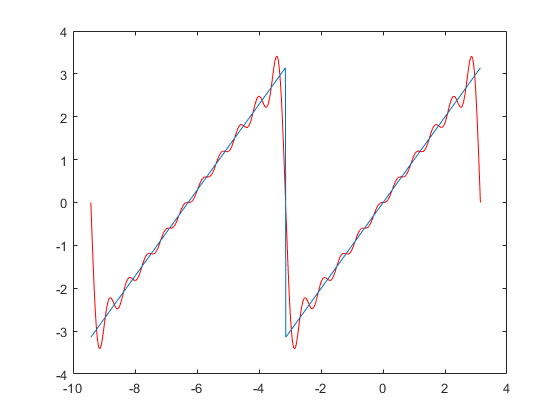

plot(rx1, ry2)